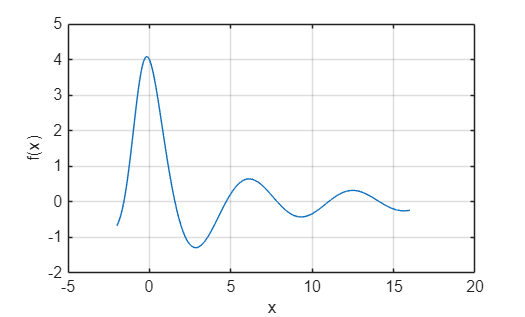

%%1번
A = [1 4 2;2 4 100;7,9,7;3,pi,42];
B = log(A);

a = B(2,:);
b = sum(a);
c = B(:,2).*A(:,1);
d = max(c);
e = A(1,:)./B(1:3,3)';
sum_e = sum(e);

%%3번
x = -2:0.01:16;
fx = (4*cos(x)) ./ (x + exp(-0.75*x));
plot(x, fx);
xlabel('x');
ylabel('f(x)');
grid on;



%%5번
p = [5 0 -3 7 10];
q = [4 -7 9 2];

result = conv(p, q);
p = [5 -7 2 8];
q = [6 3 -2];

[quotient, remainder] = deconv(p, q);
a = [36 -8 0 2];
b = [36 -5 4 -3];

%%4번
price = [300; 550; 400; 250; 500];

Q = [5 4 6;
     3 2 4;
     6 5 3;
     3 5 4;
     2 4 3];


C = price .* Q;

month = sum(C);
material = sum(C, 2);
total = sum(C(:));


%%2번
v0 = 50;
A = 50;
g = 9.81;
t_hit = 2 * v0 * sind(A) / g;%%충돌시간
t1 = v0 * sind(A) / g;%%최고 높이일 때 시간
y_max = v0 * sind(A) * t1 - 0.5 * g * t1^2;
disp(t_hit)

    7.8088



disp(y_max)

   74.7737



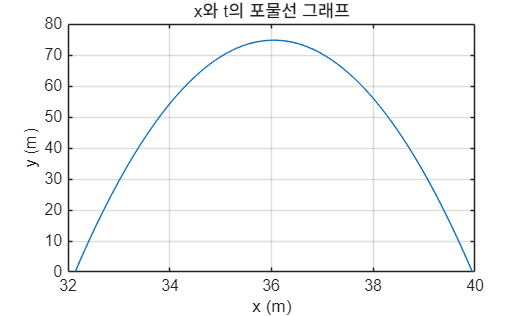

%%(b)
t = linspace(0, t_hit, 1000);
x = v0 * cosd(A) + t;
y = v0 * sind(A) * t - 0.5 * g * t.^2;

figure;
plot(x, y);
xlabel('x (m)');
ylabel('y (m)');
title('x와 t의 포물선 그래프');
grid on;


%%7번
bridges(1) = struct('location','Smith St.', 'load',80,  'year',1928, 'limit',2025);
bridges(2) = struct('location','Hope Ave.', 'load',90,  'year',1950, 'limit',2027);
bridges(3) = struct('location','Clark St.', 'load',85,  'year',1933, 'limit',2024);
bridges(4) = struct('location','North Rd.', 'load',100, 'year',1960, 'limit',2023);

bridges(3).limit = 2026;

bridges(5) = struct('location','Shore Rd.', 'load',85, 'year',1997, 'limit',2022);